clc; clear all; close all; 

## Data Summary and Visualisation

### Working Directory

% Set working directory to the current directory 
setwdtocurrent()
addpath('src');
addpath("data/raw/")

### Import Data

Loading Sheet 1:

No0x2E2WT


Loading Sheet 2:

No0x2E3


Loading Sheet 3:

No0x2E14WT


Loading Sheet 4:

No0x2E39WT


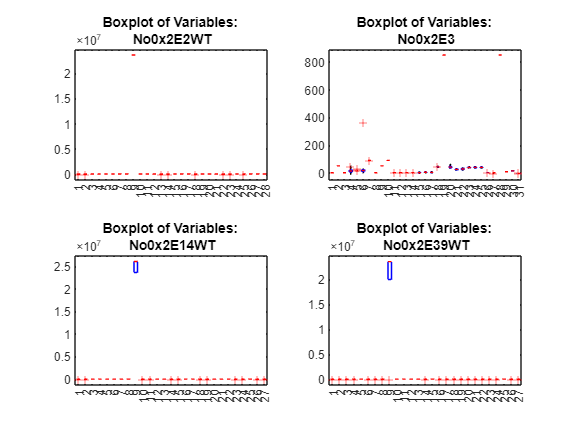

%Suppress warnings
warning('off');

% Define the Excel file name
excelFileName = 'data.xlsx';

% Get the sheet names from the Excel file
[~, sheetNames] = xlsfinfo(excelFileName);

% Loop through each sheet, read it into a table 
for i = 1:length(sheetNames)
    fprintf("Loading Sheet %d:", i)
    sheetName = sheetNames{i};
    % Generate a valid variable name in MATLAB
    tableName = genvarname(sheetName); 
    tableData = readtable(excelFileName, 'Sheet', sheetName, 'ReadVariableNames', true);
    % Save the table with the sheet name as the table name
    assignin('base', tableName, tableData);
    %Display the table name
    disp(tableName)

    % % Save the summary stats in an excel file
    currentDir = pwd;
    mainFolder = 'data';
    subFolder = 'processed';
    destinationFolder = fullfile(currentDir, mainFolder, subFolder);

    % Create the folder if it does not exist
    if ~exist(fullfile(currentDir, destinationFolder), 'dir')
        mkdir(fullfile(destinationFolder));
    end

    % Define the output file name
    outputFileName = fullfile(destinationFolder, 'summary.xls');
    
    % Write the table to Excel
    writetable(summarystats(eval(tableName)), outputFileName, 'Sheet', i);

    
    % Visualize the data in the table using boxplots
    folderName = 'images';

    % Create a folder named "images" if it does not exist
    if ~exist(fullfile(currentDir, folderName), 'dir')
        mkdir(fullfile(folderName));
    end
    subplot(2, 2, i)
    boxplot(table2array(eval(tableName)))
    title([sprintf('Boxplot of Variables: \n'), tableName])

    if i==length(sheetNames)
        saveas(gcf, fullfile('images', 'unscaledBoxplot.png'));
        % close(gcf); 
    end
end

## Data Pretreatment

### Discard the dataset for `WT3`

clear No0x2E3;

### Drop one of the columns in the dataset for `WT2`

No0x2E2WT = removevars(No0x2E2WT, "x28");

### Drop two columns in the three datasets

dataTables = {'No0x2E2WT', 'No0x2E14WT', 'No0x2E39WT'};
% These variables are constant in the healthy turbine data
varToRemove = {'x12', 'x15'};
for i = 1:numel(dataTables)
    tableName = dataTables{i};
    for j = 1:numel(varToRemove)
        variableName = varToRemove{j};
        eval([tableName, ' = removevars(', tableName, ', "', variableName, '");']);
    end
end

### Drop the observation with the missing value

No0x2E14WT = rmmissing(No0x2E14WT);

### Data centering and scaling

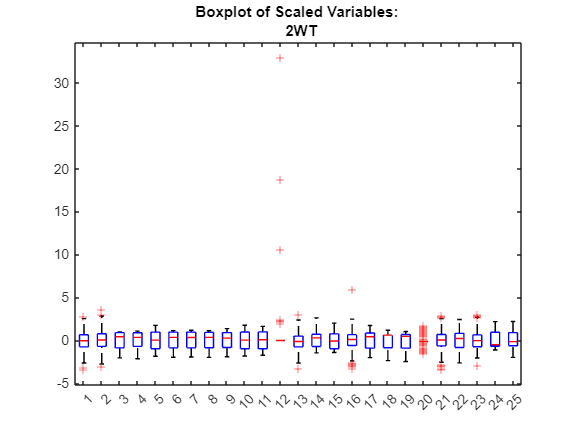

% % Center and scale the data for the healthy turbine
model.varNames = No0x2E2WT.Properties.VariableNames;

[model.No0x2E2WT, model.mu, model.sigma] = zscore(table2array(No0x2E2WT));

% Create a boxplot for the centered and scaled healthy turbine
figure;
boxplot(model.No0x2E2WT);
title(sprintf('Boxplot of Scaled Variables: \n 2WT'));

saveas(gcf, fullfile('images', 'No0x2E2Boxplot.png'));

model.No0x2E14WT

model = struct with fields:
      varNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x13'  'x14'  'x16'  'x17'  'x18'  'x19'  'x20'  'x21'  'x22'  'x23'  'x24'  'x25'  'x26'  'x27'}
     No0x2E2WT: [1570x25 double]
            mu: [-0.0074 -0.0116 26.3116 29.2803 315.3096 41.0436 40.9062 41.0798 2.3575e+07 320.6220 1.3203e+03 0.0110 -0.7541 223.6841 9.0433 685.0910 50.0023 17.6232 22.9118 10.7356 5.1643 5.4798 16.9228 53.2114 59.8223]
         sigma: [0.0455 0.0739 1.4622 1.6317 117.1357 2.2889 2.2389 2.2330 397.9615 117.0907 146.6609 0.0144 1.5969 15.4066 1.4409 2.1488 0.0454 0.3024 0.2864 0.2197 4.6742 0.7837 2.5627 3.1453 1.9001]
    No0x2E14WT: [685x25 double]


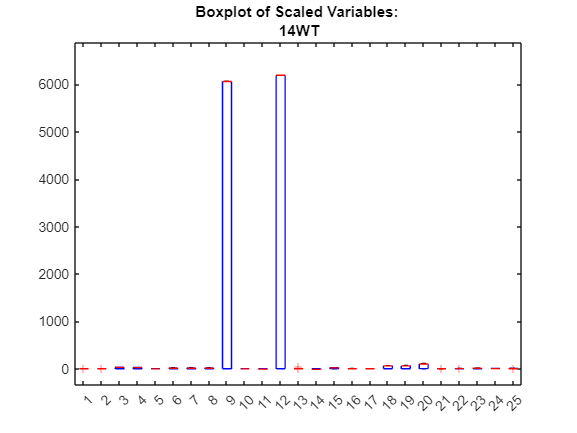

model.No0x2E39WT

model = struct with fields:
      varNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x13'  'x14'  'x16'  'x17'  'x18'  'x19'  'x20'  'x21'  'x22'  'x23'  'x24'  'x25'  'x26'  'x27'}
     No0x2E2WT: [1570x25 double]
            mu: [-0.0074 -0.0116 26.3116 29.2803 315.3096 41.0436 40.9062 41.0798 2.3575e+07 320.6220 1.3203e+03 0.0110 -0.7541 223.6841 9.0433 685.0910 50.0023 17.6232 22.9118 10.7356 5.1643 5.4798 16.9228 53.2114 59.8223]
         sigma: [0.0455 0.0739 1.4622 1.6317 117.1357 2.2889 2.2389 2.2330 397.9615 117.0907 146.6609 0.0144 1.5969 15.4066 1.4409 2.1488 0.0454 0.3024 0.2864 0.2197 4.6742 0.7837 2.5627 3.1453 1.9001]
    No0x2E14WT: [685x25 double]
    No0x2E39WT: [1405x25 double]


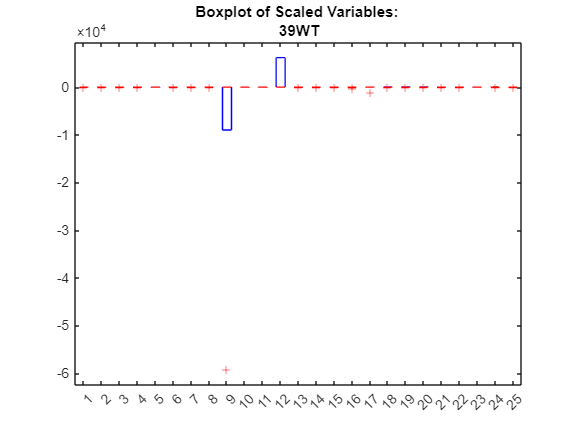


% %Apply the healthy turbine center and standard deviation to the faulty turbines
% Define the turbine numbers 
turbineNumbers = [14, 39];

% Create a loop to process each turbine
for i = 1:length(turbineNumbers)
    turbineNumber = turbineNumbers(i);
    
    % Access the corresponding windTurbine table
    windTurbine = evalin('base', sprintf('No0x2E%dWT', turbineNumber));
    
    % Normalize the data for the current turbine using the healthy turbine mean and standard deviation 
    fprintf(['model.' 'No0x2E' num2str(turbineNumber) 'WT'])
    model.(['No0x2E' num2str(turbineNumber) 'WT']) = normalize(table2array(windTurbine), 'Center', model.mu, 'Scale', model.sigma) 
    
    
    % Create a boxplot for the current turbine
    figure;
    boxplot(model.(['No0x2E' num2str(turbineNumber) 'WT']));
    title([sprintf('Boxplot of Scaled Variables: \n'), num2str(turbineNumber) 'WT'])

    saveas(gcf, fullfile('images', ['No0x2E' num2str(turbineNumber) 'Boxplot.png']));
    % close(gcf);
end

## Model Calibration

### Selection of Optimal Number of Principal Components 

#### **Cumulative Explained Variance Plot**

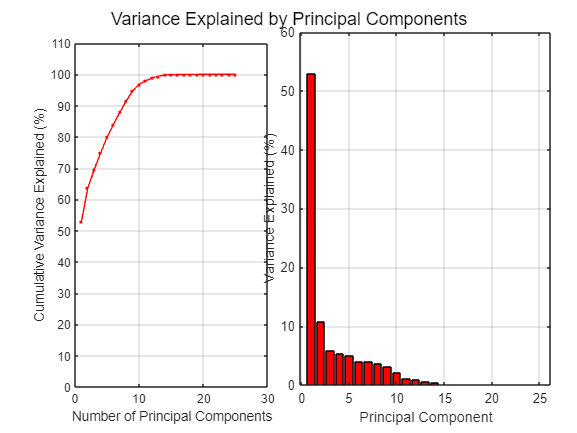

[model.P, model.T, model.latent, model.tsq, model.explained] = pca(model.No0x2E2WT, 'Centered', false);
model.explVar = 100 * cumsum(model.latent)/ sum(model.latent);

figure; 
subplot(1, 2, 1);
plot(1:length(model.explVar), model.explVar, 'r.-', 'LineWidth', 1); 
ylim([0 110]);
xlabel("Number of Principal Components");
ylabel("Cumulative Variance Explained (%)");
% title("Cumulative PC Contribution");
grid on;
subplot(1, 2, 2);
bar(model.explained, 'r');
xlabel("Principal Component");
ylabel("Variance Explained (%)");
% title("Individual PC Contribution");
grid on;
sgtitle("Variance Explained by Principal Components");
% Adjust subplot positions for better visualization
pos = get(gca, 'Position');
pos(1) = pos(1) - 0.05; 
pos(3) = pos(3) + 0.1;
set(gca, 'Position', pos);

#### **Leave-One-Out Cross Validation **

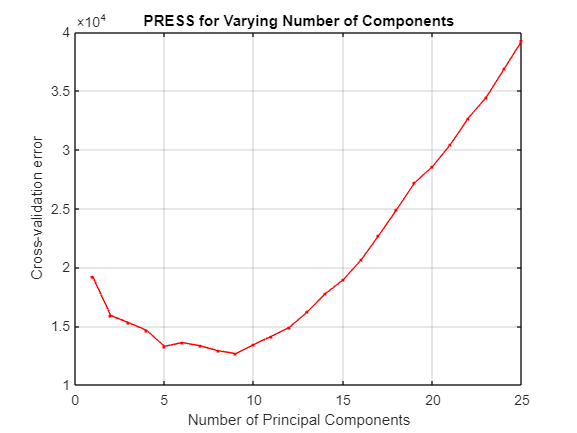

pcaloocv(model.No0x2E2WT)

### Optimal Model Calibration

% Specify the number of PCs to retain 
ncomp = 9;

## Control Chart Development

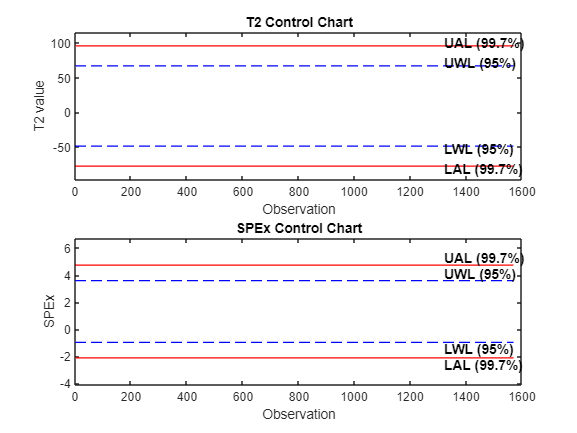

model.T2 = t2comp(model.No0x2E2WT, model.P, model.latent, ncomp);
model.Q = qcomp(model.No0x2E2WT, model.P, ncomp);

n = 2;
model.LowerWarLimT2 = mean(model.T2) - n * std(model.T2);
model.UpperWarLimT2 = mean(model.T2) + n * std(model.T2);
model.LowerWarLimQ = mean(model.Q)  - n * std(model.Q);
model.UpperWarLimQ = mean(model.Q)  + n * std(model.Q);

m = 3;
model.LowerActLimT2 = mean(model.T2) - m * std(model.T2);
model.UpperActLimT2 = mean(model.T2) + m * std(model.T2);
model.LowerActLimQ = mean(model.Q)  - m * std(model.Q);
model.UpperActLimQ = mean(model.Q)  + m * std(model.Q);

objN = 1:length(model.No0x2E2WT(:,1));

figure;
subplot(2, 1, 1);
tchart = plot([min(objN), max(objN)], [model.LowerWarLimT2, model.LowerWarLimT2], 'b--', ...
               [min(objN), max(objN)], [model.UpperWarLimT2, model.UpperWarLimT2], 'b--', ...
               [min(objN), max(objN)], [model.LowerActLimT2, model.LowerActLimT2], 'r', ...
               [min(objN), max(objN)], [model.UpperActLimT2, model.UpperActLimT2], 'r');
hold on;
text(max(objN)-250, model.LowerWarLimT2 - 4, 'LWL (95%)', 'FontSize', 10, 'Color', 'black', 'FontWeight', 'bold');
text(max(objN)-250, model.LowerActLimT2 - 4, 'LAL (99.7%)', 'FontSize', 10, 'Color', 'black', 'FontWeight', 'bold');
text(max(objN)-250, model.UpperWarLimT2 + 4, 'UWL (95%)', 'FontSize', 10, 'Color', 'black', 'FontWeight', 'bold');
text(max(objN)-250, model.UpperActLimT2 + 4, 'UAL (99.7%)', 'FontSize', 10, 'Color', 'black', 'FontWeight', 'bold');
ylim([model.LowerActLimT2 - 20, model.UpperActLimT2 + 20]);
title('T2 Control Chart');
xlabel("Observation");
ylabel("T2 value");
subplot(2, 1, 2);
spex_chart = plot([min(objN), max(objN)], [model.LowerWarLimQ, model.LowerWarLimQ], 'b--', ...
     [min(objN), max(objN)], [model.UpperWarLimQ, model.UpperWarLimQ], 'b--', ...
     [min(objN), max(objN)], [model.LowerActLimQ, model.LowerActLimQ], 'r', ...
     [min(objN), max(objN)], [model.UpperActLimQ, model.UpperActLimQ], 'r');
hold on;
text(max(objN)-250, model.LowerWarLimQ - 0.5, 'LWL (95%)', 'FontSize', 10, 'Color', 'black', 'FontWeight', 'bold');
text(max(objN)-250, model.LowerActLimQ - 0.5, 'LAL (99.7%)', 'FontSize', 10, 'Color', 'black', 'FontWeight', 'bold');
text(max(objN)-250, model.UpperWarLimQ + 0.5, 'UWL (95%)', 'FontSize', 10, 'Color', 'black', 'FontWeight', 'bold');
text(max(objN)-250, model.UpperActLimQ + 0.5, 'UAL (99.7%)', 'FontSize', 10, 'Color', 'black', 'FontWeight', 'bold');
ylim([model.LowerActLimQ - 2, model.UpperActLimQ + 2]);
title('SPEx Control Chart');
xlabel("Observation");  
ylabel("SPEx");

## Fault Identification

limits = [model.UpperWarLimT2, model.UpperActLimT2, model.UpperWarLimQ, model.UpperActLimQ];

### Control Charts for Healthy Turbine (2WT)

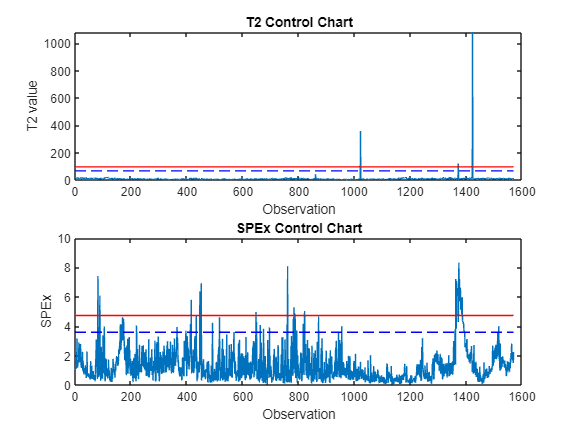

[model.T22WT, model.Q2WT, model.Class2WT] = faultIdentification(model.No0x2E2WT, limits, model.P, model.latent, ncomp, 0);

### Control Charts for Faulty Turbines

#### 14WT

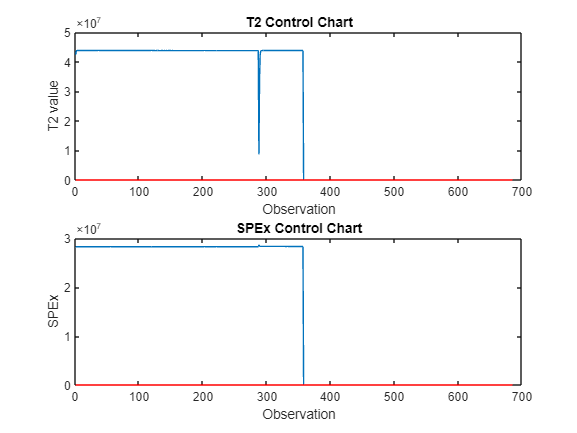

[model.T214WT, model.Q14WT, model.Class14WT] = faultIdentification(model.No0x2E14WT, limits, model.P, model.latent, ncomp, 0);

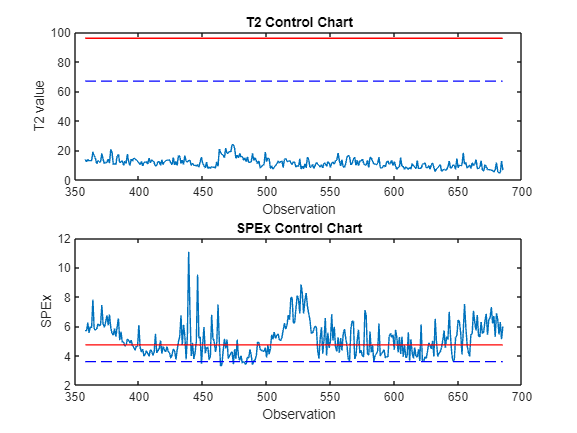

[~, ~, ~] = faultIdentification(model.No0x2E14WT, limits, model.P, model.latent, ncomp, 1);

#### 39WT

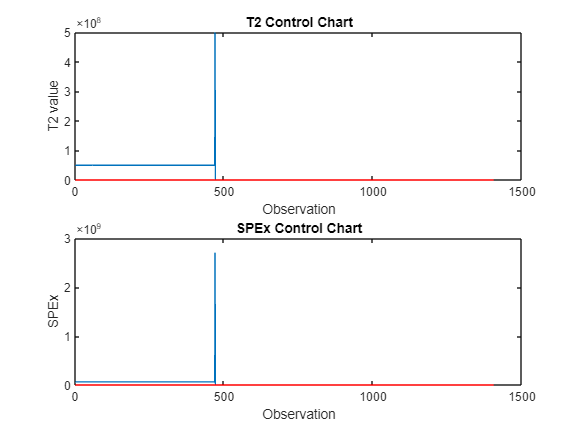

[model.T239WT, model.Q39WT, model.Class39WT] = faultIdentification(model.No0x2E39WT, limits, model.P, model.latent, ncomp, 0);

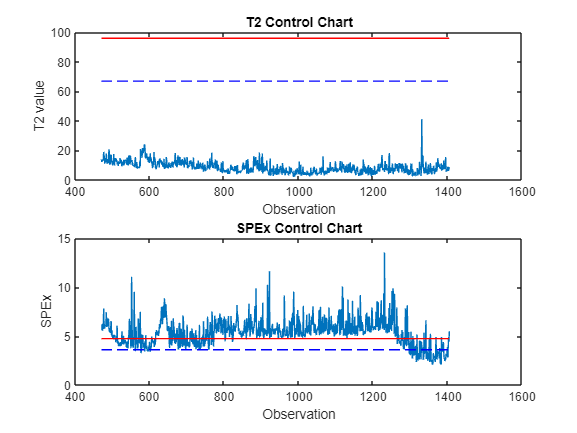

[~, ~, ~] = faultIdentification(model.No0x2E39WT, limits, model.P, model.latent, ncomp, 1);

Plot

loadings = scomp(model.No0x2E2WT(1,:), model.P, ncomp)
figure;
bar(loadings);
xlabel('Variable Index');
ylabel('Loadings');
